%Name: Martins Davis Bernhards 
%Student number: 552135
%Assignments week 4 


%Assignment 1

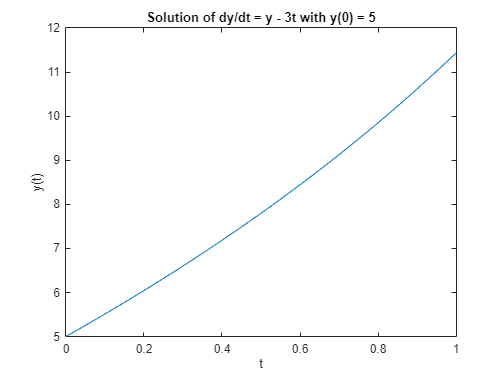

t = linspace(0, 1, 100);

% Analytical solution to the differential equation
y = 3*(t + 1) + 2*exp(t);

% Plot the solution
plot(t, y);
xlabel('t');
ylabel('y(t)');
title('Solution of dy/dt = y - 3t with y(0) = 5');

%Assignment 2

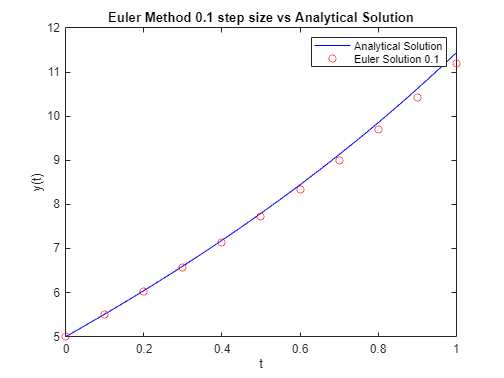

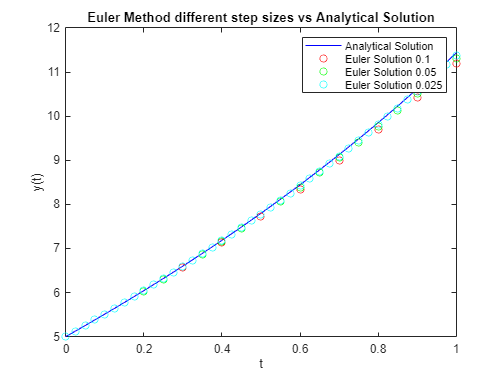

error_ratio1 = 0.5218

error_ratio2 = 0.5112

t0 = 0;
t_end = 1;
dt = 0.1;
y0 = 5;

% Analytical solution
t_analytical = linspace(t0, t_end, 100);
y_analytical = 3*(t_analytical + 1) + 2*exp(t_analytical);

% Euler
[t_euler, y_euler] = Euler(@righthandside, t_end, dt, t0, y0);

% Plot
figure;
plot(t_analytical, y_analytical, 'b-', 'DisplayName', 'Analytical Solution');
hold on;
plot(t_euler, y_euler, 'ro', 'DisplayName', 'Euler Solution 0.1');
legend;
xlabel('t');
ylabel('y(t)');
title('Euler Method 0.1 step size vs Analytical Solution');
hold off;

%Assignment 3

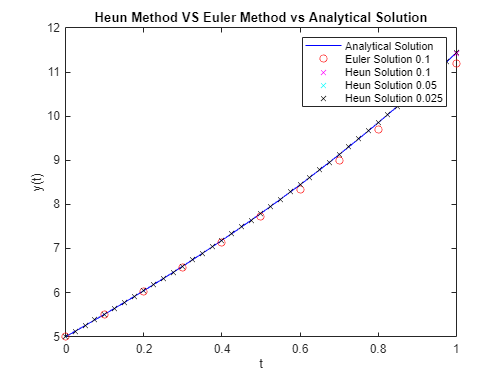

t0 = 0;
t_end = 1;
dt = 0.1;
y0 = 5;

% Analytical solution
t_analytical = linspace(t0, t_end, 100);
y_analytical = 3*(t_analytical + 1) + 2*exp(t_analytical);

% Euler
[t_euler, y_euler] = Euler(@righthandside, t_end, dt, t0, y0);

% Heun
[t_heun, y_heun] = Heun(@righthandside, t_end, dt, t0, y0);

dt1 = 0.05;
[t_heun1, y_heun1] = Heun(@righthandside, t_end, dt1, t0, y0);

dt2 = 0.025;
[t_heun2, y_heun2] = Heun(@righthandside, t_end, dt2, t0, y0);

% Plot 0.05 and 0.025
figure;
plot(t_analytical, y_analytical, 'b-', 'DisplayName', 'Analytical Solution');
hold on;
plot(t_euler, y_euler, 'ro', 'DisplayName', 'Euler Solution 0.1');
plot(t_heun, y_heun, 'mx', 'DisplayName', 'Heun Solution 0.1');
plot(t_heun1, y_heun1, 'cx', 'DisplayName', 'Heun Solution 0.05');
plot(t_heun2, y_heun2, 'kx', 'DisplayName', 'Heun Solution 0.025');
legend;
xlabel('t');
ylabel('y(t)');
title('Heun Method VS Euler Method vs Analytical Solution');


% Calculate errors at t=1
error01 = abs(y_heun(end) - y_analytical(end));
error005 = abs(y_heun1(end) - y_analytical(end));
error0025 = abs(y_heun2(end) - y_analytical(end));

% Error ratios
error_ratio1 = error005 / error01

error_ratio1 = 0.2596

error_ratio2 = error0025 / error005

error_ratio2 = 0.2548

%Assignment 4

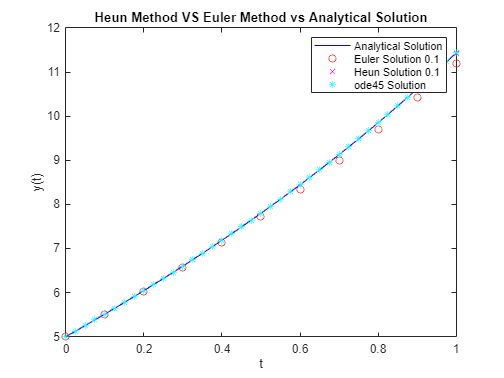

t0 = 0;
t_end = 1;
dt = 0.1;
y0 = 5;

% Analytical solution
t_analytical = linspace(t0, t_end, 100);
y_analytical = 3*(t_analytical + 1) + 2*exp(t_analytical);

% Euler
[t_euler, y_euler] = Euler(@righthandside, t_end, dt, t0, y0);

% Heun
[t_heun, y_heun] = Heun(@righthandside, t_end, dt, t0, y0);

% Using ode45
[t_ode45, y_ode45] = ode45(@righthandside, [t0 t_end], y0);

% Plot 0.05 and 0.025
figure;
plot(t_analytical, y_analytical, 'b-', 'DisplayName', 'Analytical Solution');
hold on;
plot(t_euler, y_euler, 'ro', 'DisplayName', 'Euler Solution 0.1');
plot(t_heun, y_heun, 'mx', 'DisplayName', 'Heun Solution 0.1');
plot(t_ode45, y_ode45, 'c*', 'DisplayName', 'ode45 Solution');
legend;
xlabel('t');
ylabel('y(t)');
title('Heun Method VS Euler Method vs Analytical Solution');